# Robotics, Vision & Control 3e: for MATLAB

# Appendices

Copyright 2022-2023 Peter Corke, Witold Jachimczyk, Remo Pillat

## Appendix C: Geometry

### C.1 Euclidean Geometry

#### C.1.2 Lines

#### C.1.2.2 Lines in 3D and Plücker Coordinates

P = [2 3 4]; Q = [3 5 7];
L = Plucker(P,Q)

 
L = 
{ 1  -2  1; -1  -2  -3}


L.v

ans =      1    -2     1


L.w

ans =     -1    -2    -3


L.skew

ans =      0     1     2    -1
    -1     0     1    -2
    -2    -1     0    -3
     1     2     3     0


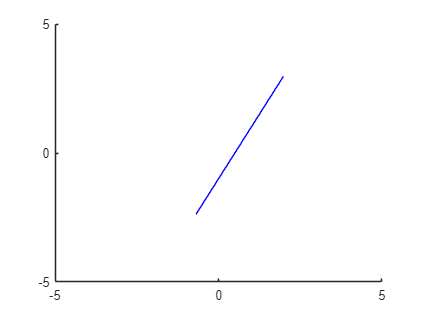

axis([-5 5 -5 5 -5 5]);
L.plot("b");

L.point([0 1 2])

ans =     0.5714    0.1429   -0.2857
    0.3042   -0.3917   -1.0875
    0.0369   -0.9262   -1.8893


[x,d] = L.closest([1 2 3]) %#ok<*ASGLU> 

x =     1.5714    2.1429    2.7143


d = 0.6547

L.intersect_plane([0 0 1 0])

ans =     0.6667    0.3333         0


#### C.1.4 Ellipses and Ellipsoids

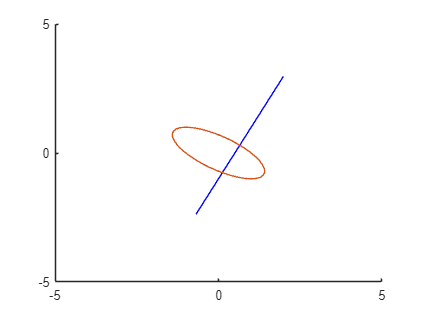

E = [1 1;1 2];
plotellipse(E)

[x,e] = eig(E)

x =    -0.8507    0.5257
    0.5257    0.8507


e =     0.3820         0
         0    2.6180


r = 1./sqrt(diag(e))

r =     1.6180
    0.6180


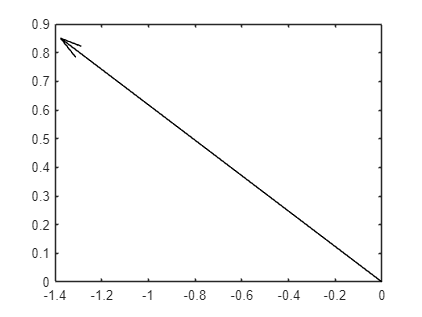

p = x(:,1)*r(1); quiver(0,0,p(1),p(2),0,"k");

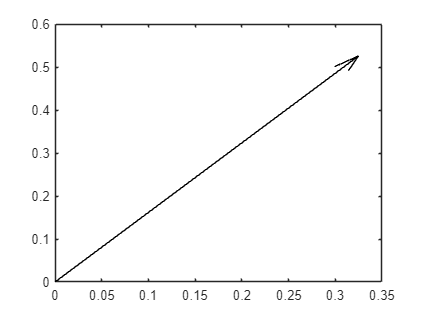

p = x(:,2)*r(2); quiver(0,0,p(1),p(2),0,"k");

atan2d(x(2,1),x(1,1))

ans = 148.2825

#### C.1.4.1 Drawing an Ellipse

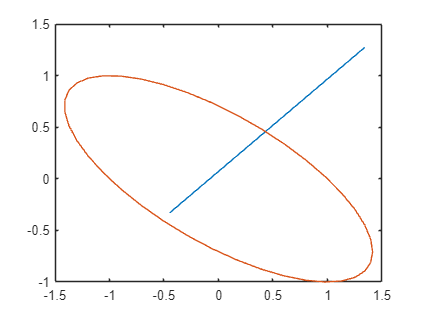

E = [1 1; 1 2];
th = linspace(0,2*pi,50);
y = [cos(th);sin(th)];
x = inv(sqrtm(E))*y;
plot(x(:,1),x(:,2));
plotellipse(E)

#### C.1.4.2 Fitting an Ellipse to Data

rng(0);  % reset random number generator
x = [];  % empty point set
while size(x,2) < 500
    p = (rand(2,1)-0.5)*4;
    if norm(p'*E*p) <= 1
        x = [x p];
    end
end
plot(x(1,:),x(2,:),".")
% compute the moments
m00 = mpq_point(x,0,0);
m10 = mpq_point(x,1,0);
m01 = mpq_point(x,0,1);
xc = m10/m00; yc = m01/m00;
% compute second moments relative to centroid
x0 = x - [xc; yc];
m20 = mpq_point(x0,2,0);
m02 = mpq_point(x0,0,2);
m11 = mpq_point(x0,1,1);
% compute the moments and ellipse matrix
J = [m20 m11;m11 m02];
E_est = m00*inv(J)/4;
E_est

E_est =     0.9914    0.9338
    0.9338    1.9087


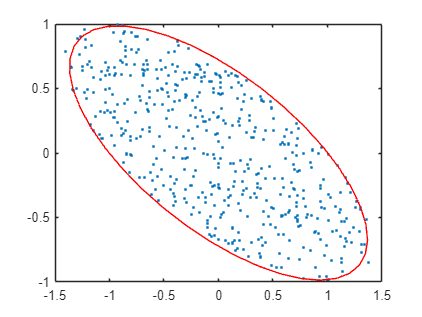

plotellipse(E_est,"r")

### C.2 Homogeneous Coordinates

#### C.2.1 Two Dimensions

#### C.2.1.1 Points and Lines

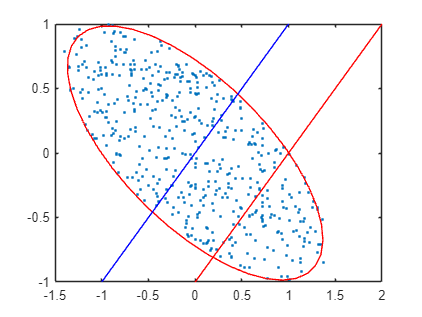

l1 = [1 -1 0];
l2 = [1 -1 -1];
plothomline(l1,"b")
plothomline(l2,"r")

cross(l1, l2)

ans =      1     1     0


## Appendix E: Linearization, Jacobians, and Hessians

### E.4 Deriving Jacobians

zrange = @(xi,xv,w) ...
      [sqrt((xi(1)-xv(1))^2 + (xi(2)-xv(2))^2) + w(1);
       atan((xi(2)-xv(2))/(xi(1)-xv(1)))-xv(3) + w(2)];
xv = [1 2 pi/3]; xi = [10 8]; w= [0,0];
h0 = zrange(xi,xv,w)

h0 =    10.8167
   -0.4592


d = 0.001;
J = [zrange(xi,xv+[1 0 0]*d,w)-h0 ...
     zrange(xi,xv+[0 1 0]*d,w)-h0 ...
     zrange(xi,xv+[0 0 1]*d,w)-h0]/d

J =    -0.8320   -0.5547         0
    0.0513   -0.0769   -1.0000


syms xi yi xv yv thetav wr wb
z = zrange([xi yi],[xv yv thetav],[wr wb])

$$z = \left(\begin{array}{c} \mathrm{wr}+\sqrt{{\left(\xi -\mathrm{xv}\right)}^{2}+{\left(\mathrm{yi}-\mathrm{yv}\right)}^{2}}\\ \mathrm{wb}-\mathrm{thetav}+\mathrm{atan}\left(\frac{\mathrm{yi}-\mathrm{yv}}{\xi -\mathrm{xv}}\right) \end{array}\right)$$

J = jacobian(z,[xv yv thetav])

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\xi -2\,\mathrm{xv}}{\sigma_{1}} & -\frac{2\,\mathrm{yi}-2\,\mathrm{yv}}{\sigma_{1}} & 0\\ \frac{\mathrm{yi}-\mathrm{yv}}{{\left(\xi -\mathrm{xv}\right)}^{2}\,\sigma_{2}} & -\frac{1}{\left(\xi -\mathrm{xv}\right)\,\sigma_{2}} & -1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\sqrt{{\left(\xi -\mathrm{xv}\right)}^{2}+{\left(\mathrm{yi}-\mathrm{yv}\right)}^{2}}\\ \sigma_{2}=\frac{{\left(\mathrm{yi}-\mathrm{yv}\right)}^{2}}{{\left(\xi -\mathrm{xv}\right)}^{2}}+1 \end{array}$$

whos J

  Name      Size            Bytes  Class    Attributes

  J         2x3                 8  sym                



Jf = matlabFunction(J);
xv = [1 2 pi/3]; xi = [10 8]; w = [0 0];
Jf(xi(1),xv(1),xi(2),xv(2))

ans =    -0.8321   -0.5547         0
    0.0513   -0.0769   -1.0000


## Appendix G: Gaussian Random Variables

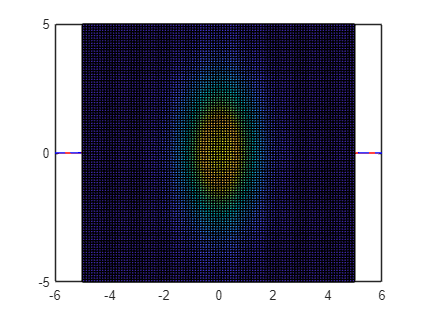

x = linspace(-6,6,500);
plot(x,gaussfunc(0,1,x),"r")
hold on
plot(x,gaussfunc(0,2^2,x),"b--")
sigma = 1; mu = 0;
g = sigma*randn(100,1) + mu;
[x,y] = meshgrid(-5:0.1:5,-5:0.1:5);
P = diag([1 2]).^2;
surfc(x,y,gaussfunc([0 0],P,x,y))

s = chi2inv(0.5,2)

s = 1.3863

## Appendix H: Kalman Filter

### H.2 Nonlinear Systems -- Extended Kalman Filter

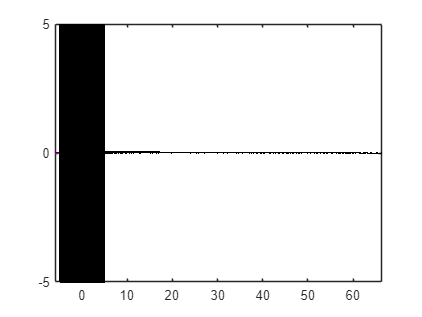

x = 2*randn(1000000,1) + 5;
y = (x+2).^2/4;
histogram(y, Normalization="pdf");

## Appendix I: Graphs

g = UGraph()

g =  
  2 dimensions
  0 nodes     
  0 edges     
  0 components

rng(10)
for i = 1:5
   g.add_node(rand(2,1));
end
g.add_edge(1,2);
g.add_edge(1,3);
g.add_edge(1,4);
g.add_edge(2,3);
g.add_edge(2,4);
g.add_edge(4,5);
g

g =  
  2 dimensions
  5 nodes     
  6 edges     
  1 components

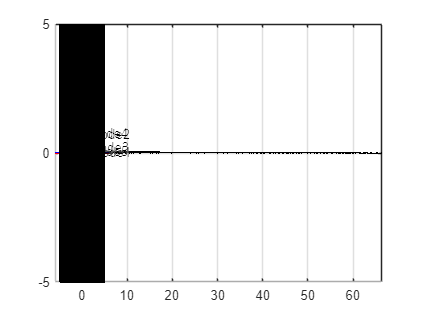

g.plot(labels=true);

g.neighbors(2)

ans =      1     3     4


e = g.edges(2)

e =      1     4     5


g.cost(e)

ans =     0.7410    0.5412    0.4357


g.nodes(5)'  % transpose for display

ans =      2     4


[n,c] = g.neighbors(2)

n =      1     3     4


c =     0.7410    0.5412    0.4357


g.about(1)

Node 1 #1@ (0.771321 0.0207519 )
  neighbors: 2 3 4 
  edges: 1 2 3 


g.closest([0.5 0.5])

ans = 3

g.path_Astar(3, 5)

ans =      3     2     4     5


## Appendix J: Peak finding

### J.1 1D Signal

load peakfit1

错误使用 load
找不到文件或目录 'peakfit1'。

plot(y,"-o")
[ypk,k] = max(y)
[ypk,k] = findpeaks(y,SortStr="descend");
ypk'  % transpose for display
k'  % transpose for display
ypk(2)/ypk(1)
range=k(1)-1:k(1)+1
p = polyfit(range,y(range),2)  % fit second-order polynomial
pd = polyder(p)  % derivative of fitted polynomial
roots(pd)  % zero value of the derivative
ypk = findpeaks(y,MinPeakDistance=5)'  % transpose for display

### J.2 2D Signal

z

$$z = \left(\begin{array}{c} \mathrm{wr}+\sqrt{{\left(\xi -\mathrm{xv}\right)}^{2}+{\left(\mathrm{yi}-\mathrm{yv}\right)}^{2}}\\ \mathrm{wb}-\mathrm{thetav}+\mathrm{atan}\left(\frac{\mathrm{yi}-\mathrm{yv}}{\xi -\mathrm{xv}}\right) \end{array}\right)$$

[zmax,i] = max(z(:))

$$zmax = \max\left(\left[\mathrm{wr}+\sqrt{{\left(\xi -\mathrm{xv}\right)}^{2}+{\left(\mathrm{yi}-\mathrm{yv}\right)}^{2}},\mathrm{wb}-\mathrm{thetav}+\mathrm{atan}\left(\frac{\mathrm{yi}-\mathrm{yv}}{\xi -\mathrm{xv}}\right)\right],\left[\right],2,\text{"omitnan"},\mathrm{thetav}\notin \mathbb{R}\vee \mathrm{wb}\notin \mathbb{R}\vee \mathrm{wr}\notin \mathbb{R}\vee \xi \notin \mathbb{R}\vee \mathrm{xv}\notin \mathbb{R}\vee \mathrm{yi}\notin \mathbb{R}\vee \mathrm{yv}\notin \mathbb{R}\right)$$

i = -1

[y,x] = ind2sub(size(z),i)

y = 1

x = 0

LMaxFinder = vision.LocalMaximaFinder(MaximumNumLocalMaxima=3, ...
                NeighborhoodSize=[3 3],Threshold=0);
LMaxFinder(z)

错误使用  () 
输入必须为数值或逻辑变量，或者为 fi 对象。

Suppress syntax warnings in this file

%#ok<*NASGU>
%#ok<*AGROW>
%#ok<*MINV> 